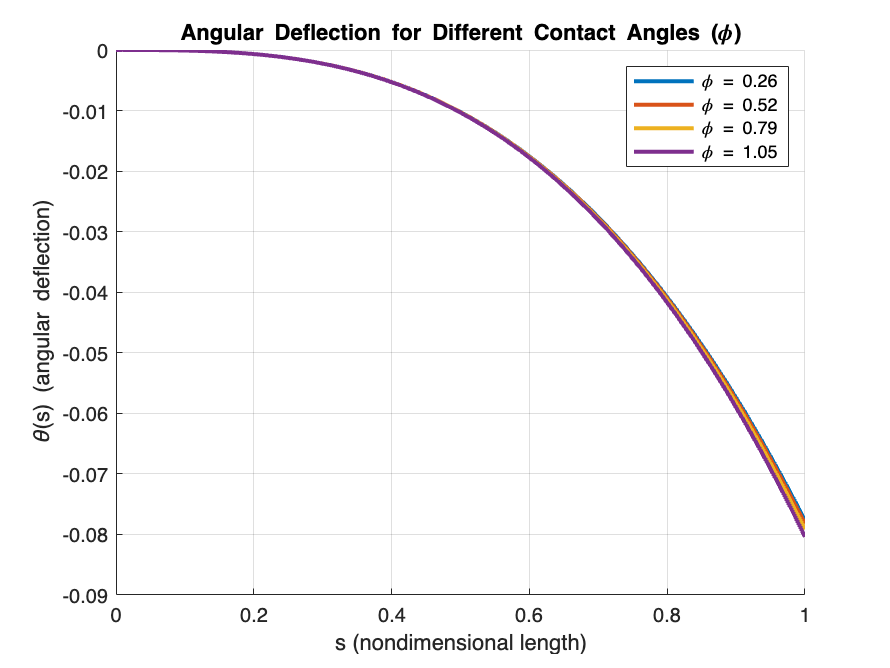

% Parameters
l_gc = 1.2;  % Dimensionless parameter
h = 0.5;     % Nondimensional liquid height
L = 1;       % Strip length
phi_values = [pi/12, pi/6, pi/4, pi/3];  % Contact angles to compare

% Initialize figure
figure;
hold on;

% Loop over different contact angles
for phi = phi_values
    % Define the system of ODEs
    ode = @(s, y) [
        y(2);  % y1' = y2
        y(3);  % y2' = y3
        -l_gc^2 * y(2) * cos(phi) - h  % y3' = -l_gc^2 * y2 * cos(phi) - h
    ];

    % Initial conditions at s = 0 (clamped end)
    y0 = [0; 0; 0];  % y1(0) = 0, y2(0) = 0, y3(0) = 0

    % Solve the system of ODEs (numerical solution)
    [s, y] = ode45(ode, [0 L], y0);

    % Plot the solution for θ(s)
    plot(s, y(:,1), 'LineWidth', 2, 'DisplayName', sprintf('\\phi = %.2f', phi));
end

% Add labels, title, and legend
xlabel('s (nondimensional length)');
ylabel('\theta(s) (angular deflection)');
title('Angular Deflection for Different Contact Angles (\phi)');
legend show;
grid on;
hold off;